clear;
close all;

frame_type = 1; %0: simquad, 1: solo, 2: simrover, 3: erle rover

filename = 'Test5/157.csv';
test_data = csvread(filename, 2, 0);

if frame_type == 0 || frame_type == 1
    max_freq = 400;
    if frame_type == 1
        max_freq = 100;
    end
    reference_motor = 0.3;
    refer_idx = find(test_data(:, 14) >= reference_motor, 1);
    reference_time = test_data(refer_idx, 1); % test_data(1, 1)
    test_data(:, 1) = test_data(:, 1)-reference_time; % reset start time
    
    isp = refer_idx;
    iep = find(test_data(:, 14) >= reference_motor,1,'last') - 2 * max_freq;
    test_data = test_data(isp:iep, :);
elseif frame_type == 2
    max_freq = 50;
    reference_motor = 0.04;
    refer_idx = find(abs(test_data(:, 16)-0.5) >= reference_motor, 1);
    reference_time = test_data(refer_idx, 1); % test_data(1, 1)
    test_data(:, 1) = test_data(:, 1)-reference_time; % reset start time
    
    isp = refer_idx;
    iep = find(abs(test_data(:, 16)-0.5) >= reference_motor,1,'last');
    test_data = test_data(isp:iep, :);
elseif frame_type == 3
    max_freq = 50;
    reference_motor = 0.02;
    refer_idx = find(abs(test_data(:, 16)-0.5) >= reference_motor, 1);
    reference_time = test_data(refer_idx, 1); % test_data(1, 1)
    test_data(:, 1) = test_data(:, 1)-reference_time; % reset start time
    
    isp = refer_idx;
    iep = find(abs(test_data(:, 16)-0.5) >= reference_motor,1,'last');
    test_data = test_data(isp:iep, :);
    test_data(:, [2,3]) = test_data(:, [2,3]) - test_data(1, [2,3]);
end


ground_truth = test_data(:, 2:13);
gt_t = test_data(:, 1) * 1e-6;



if frame_type == 0 || frame_type == 1
    max_freq = 400;
elseif frame_type == 2 || frame_type == 3
    max_freq = 50
end

filename2 = 'Test5_rerun/00000349.csv';
test_data2 = csvread(filename2, 2, 0);

time_offset = 0;

if frame_type == 0 || frame_type == 1
    refer_idx = find(test_data2(:, 14) >= reference_motor, 1) + max_freq * time_offset;
    reference_time = test_data2(refer_idx, 1); % test_data2(1, 1)
    test_data2(:, 1) = test_data2(:, 1)-reference_time; % reset start time
    
    isp = refer_idx;
    iep = find(test_data2(:, 14) >= reference_motor,1,'last') - 2 * max_freq;
    test_data2 = test_data2(isp:iep, :);
else
    refer_idx = find(abs(test_data2(:, 16)-0.5) >= reference_motor, 1);
    reference_time = test_data2(refer_idx, 1); % test_data(1, 1)
    test_data2(:, 1) = test_data2(:, 1)-reference_time; % reset start time
    
    isp = refer_idx;
    iep = find(abs(test_data2(:, 16)-0.5) >= reference_motor,1,'last');
    test_data2 = test_data2(isp:iep, :);
end

rerun = test_data2(:, 2:13);
rerun_t = test_data2(:, 1) * 1e-6;

[res_gt, res_gt_t] = resample(ground_truth, gt_t, max_freq);
[res_rerun, res_rerun_t] = resample(rerun, rerun_t, max_freq);

% % yaw adjustment
res_rerun(:, 6) = res_rerun(:, 6) + deg2rad(0);

N = min(length(res_gt_t), length(res_rerun_t)) - 2;
idx = 1:N;

cut_time = [14, 19];
cut_idx = max_freq *  cut_time;
idx = (cut_idx(1)+1) : cut_idx(2);

res_gt = res_gt(idx, :);
res_gt_t = res_gt_t(idx);
res_rerun = res_rerun(idx, :);
res_rerun_t = res_rerun_t(idx);



errors = res_rerun - res_gt;
errors(:, 4:6) = wrapToPi(errors(:, 4:6));

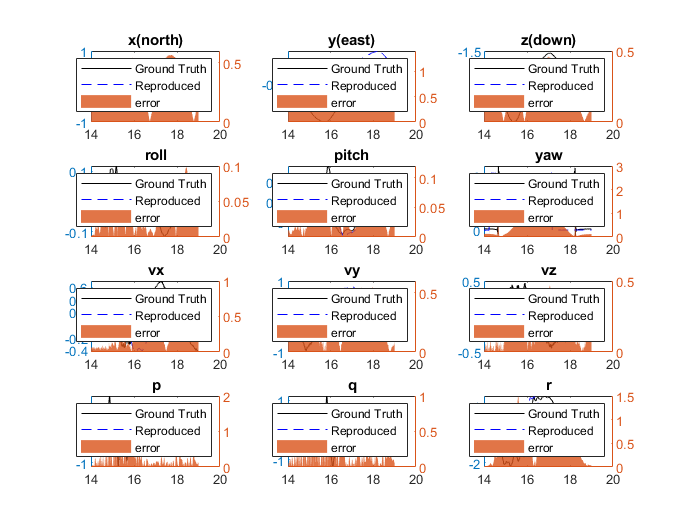

title_name = ["x(north)", "y(east)", "z(down)", "roll", "pitch", "yaw", "vx", "vy", "vz", "p", "q", "r"]; 
figure_range = [];    
% figure_range = [-10, 40, 0, 10;
%                 -10, 40, 0, 10;
%                 -10, 0, 0, 10;
%                 -0.2, 0.2, 0, 0.5;
%                 -0.2, 0.2, 0, 0.5;
%                 -2, 8, 0, 4];

        
figure;
NY=12;
for n=1:NY
    if NY > 1
        subplot(NY/3, 3, n);
    end
    title(title_name(n));
    yyaxis left
    plot(res_gt_t, res_gt(:, n),'k-');     %truth
    if n <= size(figure_range, 1)
        ylim(figure_range(n, 1:2));
    end
    hold on;
    plot(res_rerun_t, res_rerun(:, n), 'b--');                  %model prediction
    
    hold on;
    yyaxis right
    area(res_gt_t, abs(errors(:, n)), 'FaceAlpha', 0.8, 'EdgeColor', 'none');    % deviation
    if n <= size(figure_range, 1)
        ylim(figure_range(n, 3:4));
    end
    legend('Ground Truth', 'Reproduced', 'error');
end

distance_err = abs(errors(:, 1:3));
angles_err = rad2deg(abs(errors(:, 4:6)));
disp(['mean distance error: ' num2str(mean(distance_err)) ' m']);

mean distance error: 0.34069      0.8199     0.20095 m


disp(['mean angle errors: ' num2str(mean(angles_err)) ' degress']);

mean angle errors: 2.09624      2.22881      33.2857 degress


disp(['overall mean angle errors: ' num2str(mean(mean(angles_err))) ' degress'])

overall mean angle errors: 12.5369 degress


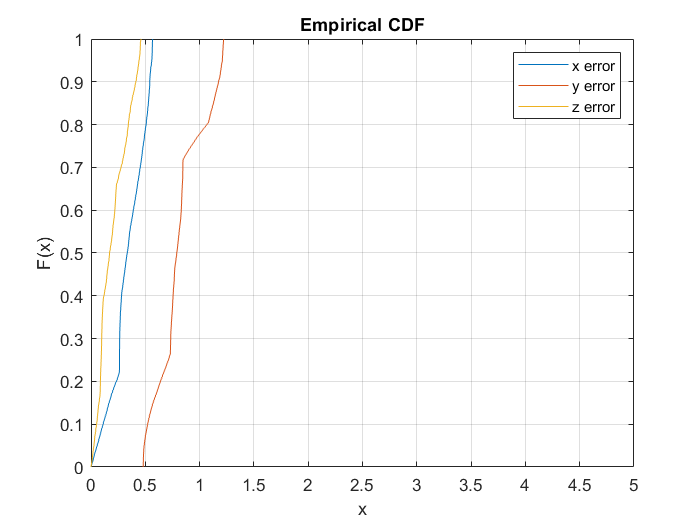

figure;
for i=1:3
    cdfplot(distance_err(:, i));
    hold on;
end
xlim([0, 5]);
legend({'x error', 'y error', 'z error'});

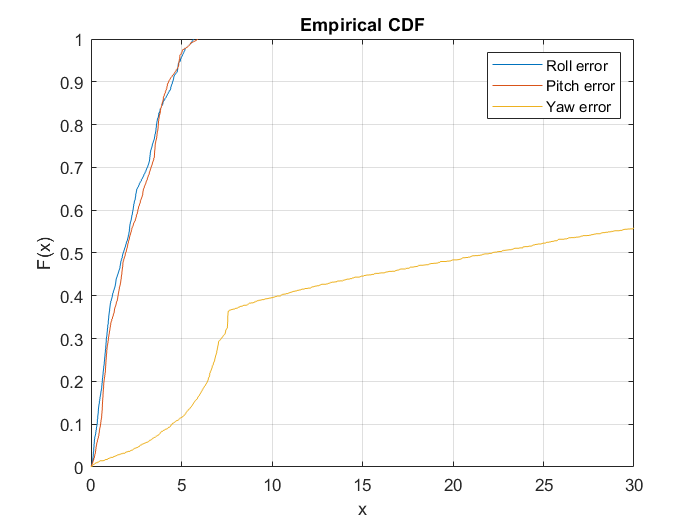

figure;
for i=1:3
    cdfplot(angles_err(:, i));
    hold on;
end
xlim([0, 30]);
legend({'Roll error', 'Pitch error', 'Yaw error'});